GFDM parameters

gfdm = struct;
gfdm.K = 8; % Subcarriers
gfdm.M = 7; % Subsymbols

gfdm.K_set = [7, 0, 1]; % Used subcarrier index(0 based)
gfdm.M_set = (1:gfdm.M-1);       % Used subsymbol index(0 based). 1 guard subsymbol.

gfdm.CP = 0;    % CP length

gfdm = GFDM_init(gfdm);

D = gfdm.D;
D_prime = gfdm.D_prime;

Es = 1;
Ts = 10^-2;

Dottorro

w = 0.0003;
eta = 1;
s_2 = 1;
V_tilde = zeros(D);
OOB_range = [5/16, 0.5];

p = rc_filter(Ts, OOB_range, 0.1);

counter = 1;
while abs(s_2) > 10^-6
    tic
    cvx_begin sdp
    variable S(D, D) hermitian nonnegative semidefinite
    expression OOB_S_a_temp(length(p), 1)
    
    OOB_S_a = (p.^2) .* PSD_S(S, OOB_range, OOB_S_a_temp, gfdm.K, gfdm.M, gfdm.K_set, gfdm.M_set, gfdm.CP, Ts, Es);
    
    minimize w*abs(trace(S*V_tilde)) + max(OOB_S_a)
    subject to
    trace(S) == D;
    sum(inv_pos(diag(S))) <= D*eta;
    
    cvx_end
    toc

 
Calling SDPT3 4.0: 6542 variables, 3193 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 3193
 dim. of sdp    var  = 336,   num. of sdp  blk  = 58
 dim. of linear var  = 101
 dim. of free   var  =  1 *** convert ublk to lblk
 number of dense column in A = 100
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+03|2.9e+00|5.6e+05| 5.600000e+02  0.000000e+00| 0:0:00| spchol 
  linsysolve: Schur complement matrix not positive definite
  switch to LU factor. sp

Elapsed time is 70.105927 seconds.


 
Calling SDPT3 4.0: 6544 variables, 3194 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 3194
 dim. of sdp    var  = 336,   num. of sdp  blk  = 58
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 101
 dim. of free   var  =  1 *** convert ublk to lblk
 number of dense column in A = 101
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+03|2.9e+00|5.6e+05| 5.600000e+02  0.000000e+00| 0:0:00| spchol 
  linsysolve: Schur complement ma

Elapsed time is 73.364915 seconds.


 
Calling SDPT3 4.0: 6544 variables, 3194 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 3194
 dim. of sdp    var  = 336,   num. of sdp  blk  = 58
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 101
 dim. of free   var  =  1 *** convert ublk to lblk
 number of dense column in A = 101
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+03|2.9e+00|5.6e+05| 5.600000e+02  0.000000e+00| 0:0:00| spchol 
  linsysolve: Schur complement ma

Elapsed time is 70.249192 seconds.


    [Q_svd, S_svd, ~] = svd(S);
    s_2 = S_svd(2, 2);
    fprintf('%d.s_2 = %f\n\n', counter, s_2);

1.s_2 = 15.034393



2.s_2 = 0.000005



3.s_2 = 0.000000



    U = Q_svd(:, 2:end);
    V_tilde = U*U';
    
    counter = counter + 1;

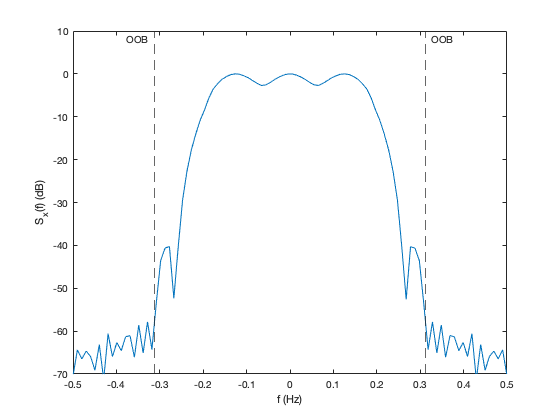

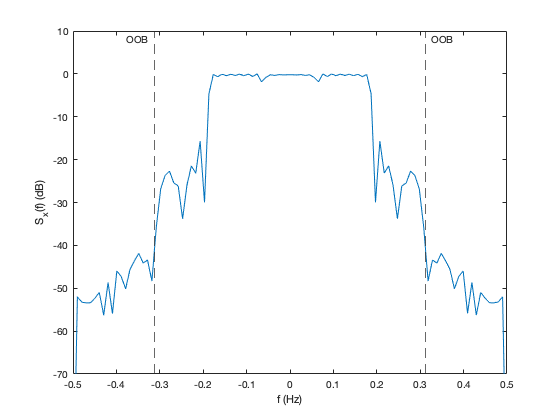

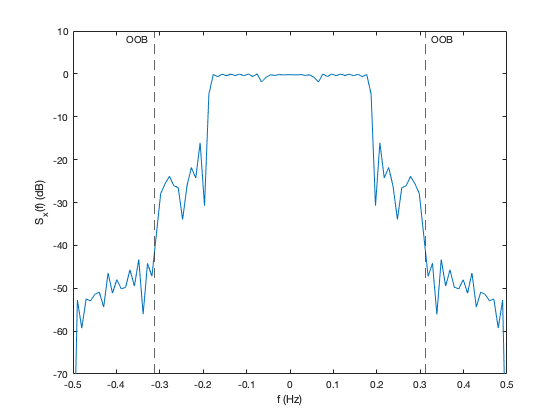

    vecG = Q_svd(:, 1) .* sqrt(S(1, 1));
    G = reshape(vecG, gfdm.K, gfdm.M);
    S_a = PSD(G, gfdm.K, gfdm.M, gfdm.K_set, gfdm.M_set, gfdm.CP, Ts, Es);
    plot_PSD(S_a, OOB_range);

end

[Q_svd, S_svd, ~] = svd(S);
vecG = Q_svd(:, 1) .* sqrt(S(1, 1));
G = reshape(vecG, gfdm.K, gfdm.M);
temp_g = (1/sqrt(gfdm.M)) * fft(G, [], 2);
g = temp_g(:)/sqrt(D);